# Robotics 2, Final exam - September 21, 2017

## Exercise 1

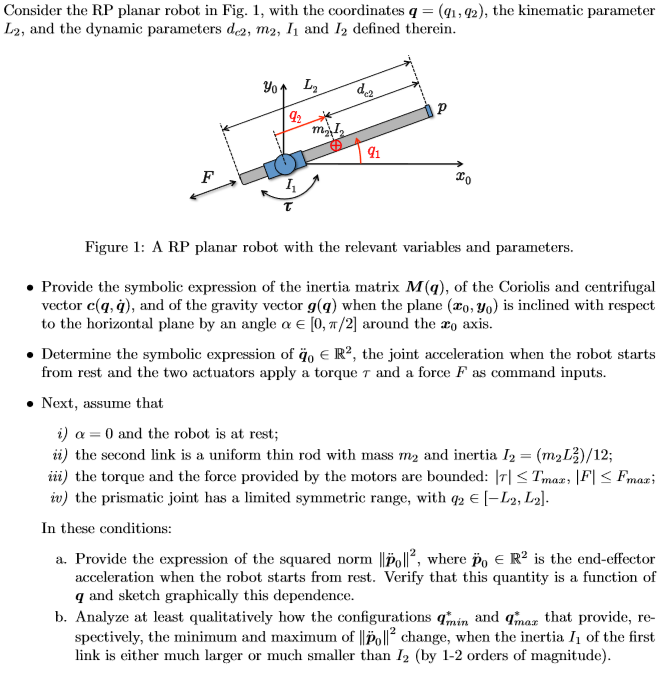

sigma = [0,1]

sigma =      0     1


$$ans = {\left(\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}+{\left(\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}$$

$$ans = {\left(\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}+{\left(\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}$$

n = length(sigma)

n = 2

I = sym('I', [n,1]);
q = sym('q', [n,1]);
m = sym('m', [n,1]);
d = sym('d', [n,1]);
qd = sym('qd', [n,1]);
l = sym('l', [n,1]);
qdd = sym('qdd', [n,1]);

syms g0 alpha tau F

g = [0 g0*sin(alpha) 0].' 

$$g = \left(\begin{array}{c} 0\\ g_{0}\,\sin\left(\alpha \right)\\ 0 \end{array}\right)$$


% adds -pi/2 to q(1) to fit the cartesian plane
dhTable = [-pi/2 0 0 q(1)-pi/2;
           0 0 q(2) 0]

$$dhTable = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & 0 & q_{1}-\frac{\pi }{2}\\ 0 & 0 & q_{2} & 0 \end{array}\right)$$

[KE, T] = getKEwithJacobian(dhTable, sigma, q,qd,l,m, I,d,0)

*** Computation of Kinetic Energy (Jacobian-based method) 


$$KE = \frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,{q_{2}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

T = 1×2 cell array
    {1×1 sym}    {1×1 sym}


T{1}

$$ans = \frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

T{2}

$$ans = \frac{m_{2}\,{q_{2}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}$$

M = getInertiaMatrixFromKE(KE,qd)

$$M = \left(\begin{array}{cc} m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

[c,S] = getcS(M,q,qd)

============= Link 1
============= Link 2


$$c = \left(\begin{array}{c} 2\,m_{2}\,q_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\\ -m_{2}\,q_{2}\,{{\mathrm{qd}}_{1}}^{2} \end{array}\right)$$

$$S = \left(\begin{array}{cc} m_{2}\,q_{2}\,{\mathrm{qd}}_{2} & m_{2}\,q_{2}\,{\mathrm{qd}}_{1}\\ -m_{2}\,q_{2}\,{\mathrm{qd}}_{1} & 0 \end{array}\right)$$

[g_q , PE, U] = getGravityWithJacobian(dhTable,q,l, m, d, g)

*** Computation of Potential Energy (Jacobian-based method) 


$$g\_q = \left(\begin{array}{c} g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)\\ g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right) \end{array}\right)$$

$$PE = g_{0}\,m_{2}\,q_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)$$

U = 1×2 cell array
    {1×1 sym}    {1×1 sym}


### Robot at rest 

subs(M*qdd + c + g_q,qd,zeros(length(qd),1))

$$ans = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\,\left(m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)\\ m_{2}\,{\mathrm{qdd}}_{2}+g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right) \end{array}\right)$$



qdd0 = solve(subs(M*qdd + c + g_q,qd,zeros(length(qd),1)) == [tau,F].', qdd)

qdd0 = struct with fields:
    qdd1: [1×1 sym]
    qdd2: [1×1 sym]


qdd0.qdd1

$$ans = \frac{\tau -g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(\alpha \right)}{m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}}$$

qdd0.qdd2

$$ans = \frac{F-g_{0}\,m_{2}\,\sin\left(\alpha \right)\,\sin\left(q_{1}\right)}{m_{2}}$$

### Expression for acceleration norm

dhTableEE = dhTable

$$dhTableEE = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & 0 & q_{1}-\frac{\pi }{2}\\ 0 & 0 & q_{2} & 0 \end{array}\right)$$

dhTableEE(2,3) = q(2)+d(2) % add this distance for endEffector

$$dhTableEE = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & 0 & q_{1}-\frac{\pi }{2}\\ 0 & 0 & d_{2}+q_{2} & 0 \end{array}\right)$$


[TTotal,TPartial]=getTransformationMatrix(dhTableEE,'alpha')

$$TTotal = \left(\begin{array}{cccc} \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)\\ -\cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TPartial = 1×2 cell array
    {4×4 sym}    {4×4 sym}



%Position of the end effector
p_EE = simplify(TTotal(1:2,4))

$$p\_EE = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(d_{2}+q_{2}\right) \end{array}\right)$$

syms q1(t) q2(t) t
p_EE = subs(p_EE,q,[q1,q2].')

$$p\_EE = \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\\ \sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right) \end{array}\right)$$

v_EE = diff(p_EE,t)

$$v\_EE = \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

a_EE = diff(v_EE,t)

$$a\_EE = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,\sigma_{2}-\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,2-\cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\sigma_{1}-\sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\sigma_{3}\\ \sin\left(q_{1}\left(t\right)\right)\,\sigma_{2}+\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,2-\sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\sigma_{1}+\cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$

a_EE0= subs(a_EE, diff([q1,q2],t),[0,0])

$$a\_EE0 = \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\\ \sin\left(q_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,\left(d_{2}+q_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}\right)$$

norm0 = simplify(a_EE0.'*a_EE0)

$$norm0 = {d_{2}}^{2}\,{\left(\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}+2\,d_{2}\,q_{2}\left(t\right)\,{\left(\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}+{q_{2}\left(t\right)}^{2}\,{\left(\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}^{2}+{\left(\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\right)}^{2}$$